# Constrained Polynomial Approximation (1D)

Course: Data Science for Engineers II

Date: 03.12.2024

Author: Dimitar Ninevski

## Prepare workspace

close all;
clear;

## Load data

load Runge.mat

## Make the data start at 0

We will make sure that the first value is 0, so that we can practice implementing homogeneous constraints.

y = y - y(1);

## Approximation without constraints

Last time we saw how to approximate without constraints and the results look as follows

degree = 5;
Vfull = vander(x);
V = Vfull(:,end-degree:end);
coefNoCon = pinv(V)*y';

## Visualization of results without constraints

nrPts = 100;
xVis = linspace(-1, 1,nrPts);
yVis = polyval(coefNoCon, xVis);
figure
plot(x, y, '.', 'MarkerSize', 12);
hold on;
plot(xVis, yVis, 'LineWidth',2);
grid on;

## Adding constraints

We will add two constraints, making sure that both end values are equal to zero.

C1 = V([1, end], :);
N1 = null(C1);
coefWithCon = N1*pinv(V*N1)*y';

## Visualization of results with constraints

yVisWithCon = polyval(coefWithCon, xVis);
plot(xVis, yVisWithCon, 'LineWidth',2);

As we can see, the constrained polynomial has the value zero at both ends, which means the constraints are fulfilled. 

## Adding derivative constraints

We can also add a constraint that makes the derivative at the start be equal to zero.

First, we need to compute the first derivative of the Vandermonde matrix. Computing the matrix M is easy

d = degree:-1:1;
M = diag(d, -1)

M =      0     0     0     0     0     0
     5     0     0     0     0     0
     0     4     0     0     0     0
     0     0     3     0     0     0
     0     0     0     2     0     0
     0     0     0     0     1     0


dV = V*M;
C2 = dV(1, :);
C = [C1; C2];
N2 = null(C);
coefWithDerCon = N2*pinv(V*N2)*y';

## Visualization of results with derivative constraints

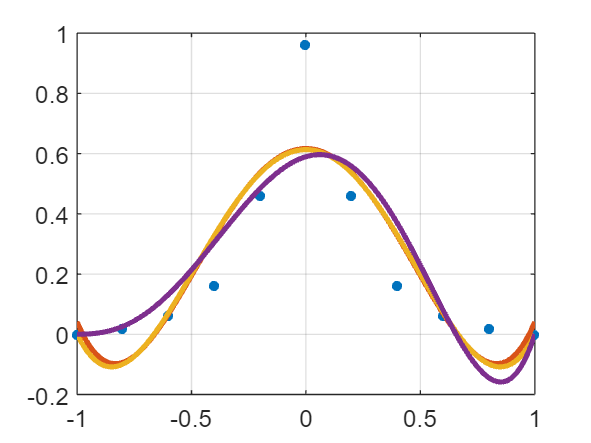

yVisWithDerCon = polyval(coefWithDerCon, xVis);
plot(xVis, yVisWithDerCon, 'LineWidth',2);

As we can see, this flattens the left part of the polynomial (making the derivative at the start zero), but as a result skews the rest of the polynomial. The constraints are fulfilled, but we need to be careful to define and implement constraints which actually make sense.

## What if the value constraints are not zero?

How could we handle the situation when the value constrain is defined as $y(x_0)=v$?

Well, if we write the upper equation out, we get

$a_2 x_1^2 +a_1x_1+a_0 = v$ or alternatively

$a_2x_1^2+a_1x_1 + (a_0-v) = 0$. So essentially, we have transformed the problem into a homogeneous problem. Once we solve $a_2x_1^2+a_1x_1 + (a_0-v) = 0$, we just need to add $v$ to the constant coefficient and we get the coefficients $a$.

The last slide of the presentation deals with this in a more general way, this is just how to deal with the case of non-homogeneous value constraints.